clear all
clf
format shortg

load("fatigue_data.mat")  % Indlæser data
min(N) % cycle data

ans =        10300


max(N) % cycle data

ans =     13000000


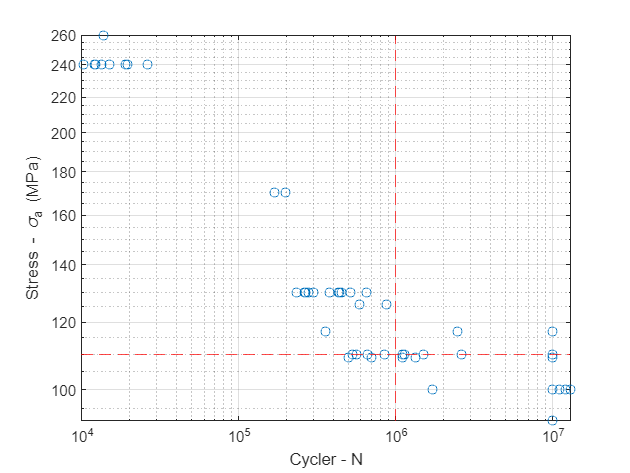

% S % stress data
% RO % run out 0 = no, 1 = yes
% data_size = size(data)


loglog(N,S,"o") %plotter data med logoritmisk scala
grid("on")

N_D = 1e6;%9.5*1e5;      %knee point cycles
S_D = 110;          %knee point stress
ylabel("Stress - \sigma_a (MPa)")
xlabel("Cycler - N")
yline(S_D, 'r--')   %markering af knæ punktet
xline(N_D, 'r--')   %markering af knæ punktet


data = [N, S, RO]; % data samles for at kunne fjere data med runouts

data2 = []; % til sorterede data uden RO og før / over knæ punktet

for i = 1:length(N)
    if N(i) < N_D && RO(i)==0  % sortere data
        data2(end+1,1:2) = data(i,1:2);
    end
end

N2 = data2(:,1);    % nye data punkter defineres
S2 = data2(:,2);    % nye data punkter defineres


Plotter ny data

figure(1)
loglog(N2, S2,"o")
ylabel("Stress - \sigma (MPa)")
xlabel("Stress - N (-)")
grid("on")
N2_log = log10(N2);
S2_log = log10(S2);

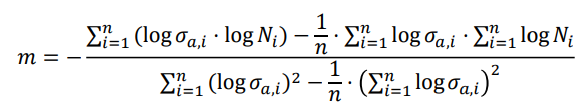

m = m_fun(S2,N2) % made as a matlab fuction in m_fun.m

m =         4.863


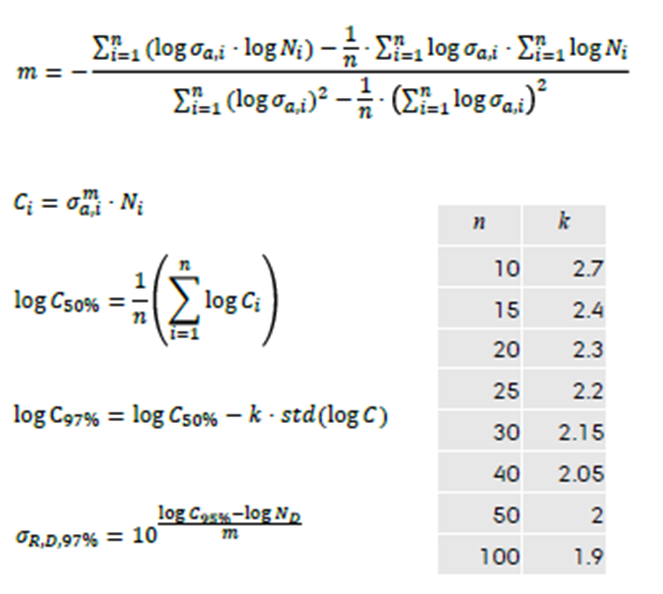

C_i = N2 .* S2.^m;
C_50_log10 = sum(log10(C_i))/length(N2)

C_50_log10 =         15.82


C_50 = 10^C_50_log10

C_50 =    6.6127e+15


sigma_RD_50 = 10^((C_50_log10 - log10(N_D))/m)

sigma_RD_50 =        104.57


N_1_plot =min(N);
N_2_plot = max(N);;
S_plot = (C_50 / N_1_plot)^(1/m) % laver vore start punkt ved at isolere sigma

S_plot =        267.95


S_plot2 = (C_50 / N_2_plot)^(1/m) % laver vore start punkt ved at isolere sigma

S_plot2 =        61.711


s_dev = std(log10(C_i))

s_dev =       0.16561


n = length(S2)

n =     31


k = 2.15 % vælges da vi har imellem 30 og 40 data punkter

k =          2.15


C_50_log10

C_50_log10 =         15.82


C_97_log10 = C_50_log10 - k*s_dev

C_97_log10 =        15.464


Cp = icdf('Normal', 1-0.97, C_50_log10, s_dev)

Cp =        15.509


sigma_RD_97 = 10^((C_97_log10 - log10(N_D))/m)

sigma_RD_97 =         88.35


C_97 = 10^C_97_log10

C_97 =    2.9129e+15


S_plot_97 = (C_97 / N_1_plot)^(1/m) % laver vore start punkt ved at isolere sigma

S_plot_97 =        226.38


S_plot_97_2 = (C_97 / N_2_plot)^(1/m) % laver vore start punkt ved at isolere sigma

S_plot_97_2 =        52.136


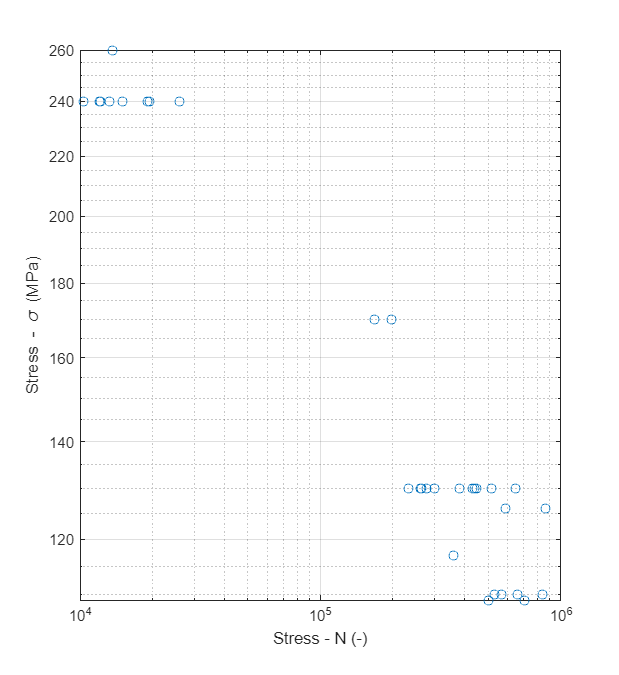


fig=gcf;
fig.Position(3:4)=[550,600];

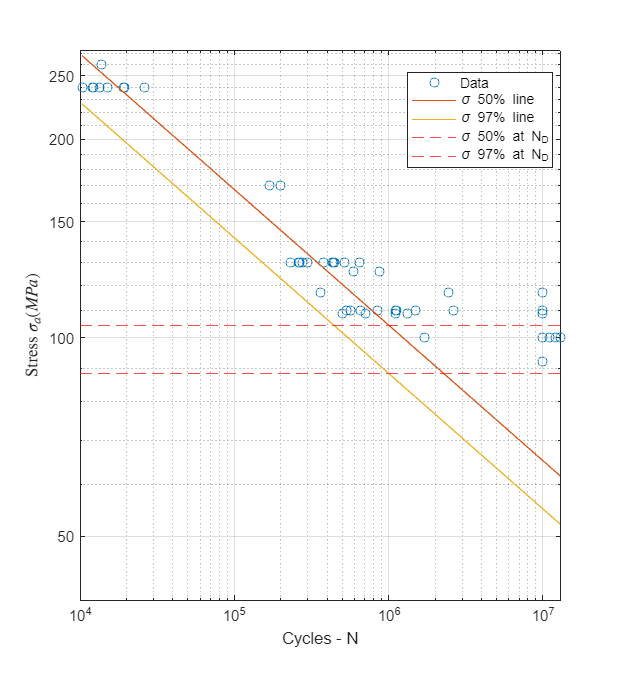

loglog(N, S,"o", DisplayName='Data')
hold on
loglog([N_1_plot, N_D, N_2_plot], [S_plot, sigma_RD_50, S_plot2], DisplayName='\sigma 50% line')
loglog([N_1_plot, N_D, N_2_plot], [S_plot_97, sigma_RD_97, S_plot_97_2], DisplayName='\sigma 97% line')

yline(sigma_RD_50,"r--", DisplayName='\sigma 50% at N_D')
yline(sigma_RD_97,"r--", DisplayName='\sigma 97% at N_D')
xlabel("Cycles - N")
ylabel("Stress $\sigma_a (MPa)$", Interpreter="latex")
ylim([40,S_plot+5])
legend('Location','best')%southoutside')
grid("on")
hold off

S150 = 150; %MPa
N_S150 = C_97/S150^m

N_S150 =         76223


N_200000 = 2e5;
S_200000 = (C_97/N_200000)^(1/m)

S_200000 =        123.01
